assert(endsWith(pwd, "non-ferromagnetic metal disk in time domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

## Distributed Current Source

#### Electromagnet

Coil.num = 2;
Coil.inner_radius = [3.75e-3  7.75e-3]; % (m)
Coil.outer_radius = [6.00e-3 10.00e-3]; % (m)
Coil.length       = [4.00e-3  4.00e-3]; % (m)
Coil.z            = [5.00e-3  5.00e-3]; % (m)

Coil.wire_diameter = [0.35e-3 0.35e-3]; % (m)
Coil.N_turns = [60 60];

#### Sensor

Sensor.num = 1;
Sensor.side_length = 0.8e-3;

Sensor.position = [0e-3 2.5e-3]';

#### Model

disk.radius = 30e-3; % (m)
disk.height = 6e-3; % (m)
disk.n_r = 30; % number of elements in r direction
disk.n_z = 10; % number of elements in z direction

r = linspace(0, disk.radius, disk.n_r+1);
z = linspace(-disk.height,0, disk.n_z+1);

Model = BuildModel2D('Cylinder', r,z);

build model took 0.01 seconds


clear disk r z

Model.conductivity = 1.91e7 * ones(1,Model.num_elms); % (S/m)
Model.relative_permittivity = 1 * ones(1,Model.num_elms); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation2D(Model, Coil, Sensor);

build governing equation took 19.35 seconds


#### Solve in time domain

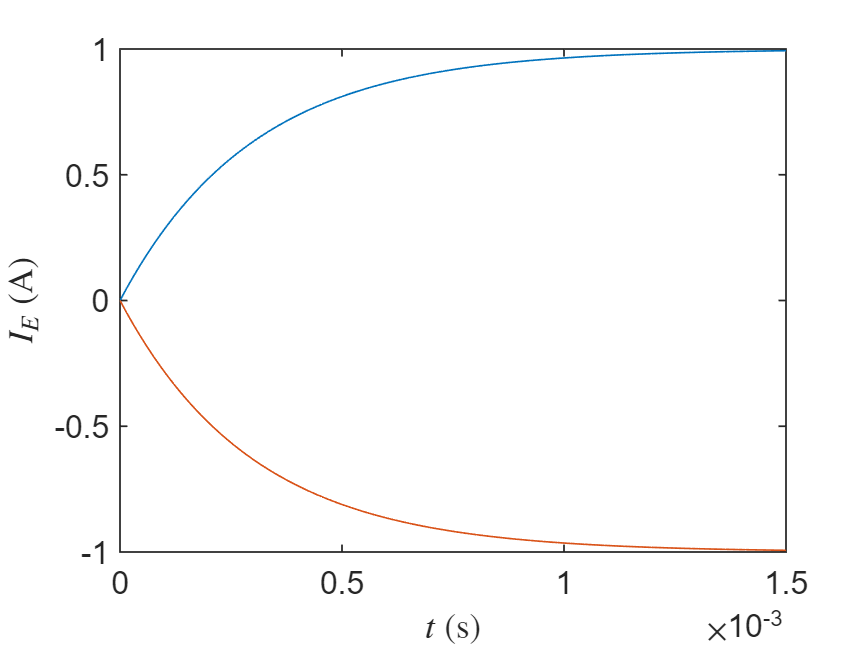

I_E_ss = [1 -1]; % (A)
tau = 3e-4; % (s)

Coil.time_domain.current = @(t) I_E_ss .* (1 - exp(-t/tau));
Coil.time_domain.current_diff = @(t) I_E_ss/tau .* exp(-t/tau);
Coil.time_domain.time_span = [0, 1.5e-3]; % (s)

t = linspace(Coil.time_domain.time_span(1), Coil.time_domain.time_span(end))';
plot(t, Coil.time_domain.current(t))
ylabel('$I_E$ (A)', 'Interpreter','latex')
xlabel('$t$ (s)', 'Interpreter','latex')

clf
clear I_E_ss tau t

[Model, Coil, Sensor] = SolveTimeDomain2D(GoverningEquation, Model, Coil, Sensor);

solve in time domain took 0.25 seconds


#### Plot result

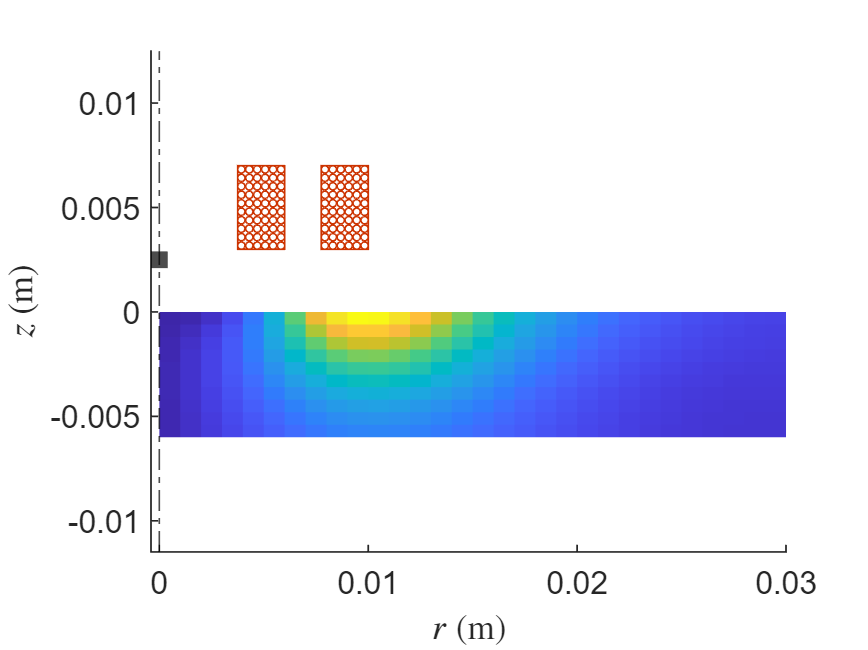

t = 0.3e-3; % (s)
[~,k] = min(abs(t - Model.time_domain.t));
PlotWorld2D(Model, Coil, Sensor, abs(Model.time_domain.J(:,:,k)) );

clf
clear t k